# this code is to fuse moments in TR

clc
clear

addpath(genpath('D:\zhiguan_wang\OneDrive - University of Glasgow\project in UK 2024\MCX\mcx_git\mcx'))
addpath(genpath('D:\zhiguan_wang\OneDrive - University of Glasgow\project in UK 2024\MCX\mcx_git\iso2mesh'))
% rmpath(genpath('D:\zhiguan_wang\OneDrive - University of Glasgow\project in UK 2024\MCX\MCXStudio'))
% rmpath(genpath('D:\zhiguan_wang\OneDrive - University of Glasgow\project in UK 2024\MCX\mcx_git\mcx'))
% addpath(genpath('D:\zhiguan_wang\OneDrive - University of Glasgow\project in UK 2024\MCX\MCXStudio'))
addpath(genpath('F:\OneDrive - University of Glasgow\project in UK 2024\MCX\mcx_git\mcx'))
addpath(genpath('F:\OneDrive - University of Glasgow\project in UK 2024\MCX\mcx_git\iso2mesh'))

## 2D CSF simulation setup

clear cfg_csf;

% % % % ------------general setting---------
cfg_csf.nphoton = 1e9;
cfg_csf.gpuid = '11'; % use two GPUs
cfg_csf.workload = [10,10];  % evenly use the two GPUs
cfg_csf.autopilot = 1;
cfg_csf.maxdetphoton = 1e7; % enough
brain_radius = 70;
cfg_csf.vol = permute(uint8(zeros([2*brain_radius,2*brain_radius])), [3, 1, 2]); % from 2d to 3d
cfg_csf.tstart = 0;
cfg_csf.tend = 3e-9;
cfg_csf.tstep = 5e-11;
cfg_csf.debuglevel = 'P'; % show progress bar
cfg_csf.unitinmm = 1;
cfg_csf.issrcfrom0 = 1;  % 1-first voxel is [0 0 0], [0]- first voxel is [1 1 1]
BinFlag = ((1:length(cfg_csf.tstart:cfg_csf.tstep:cfg_csf.tend)-1)'-1).*cfg_csf.tstep+cfg_csf.tstep/2; % the bin value of each timebin
source_angle = linspace(-pi/3,0,9)'; % angle range of source angle
det_angle = linspace(-pi/3,pi/3,17)'; % angle range of det angle
% source_angle = linspace(-pi/3,0,5)'; % angle range of source angle
% det_angle = linspace(-pi/3,pi/3,9)'; % angle range of det angle
SD_dist = abs(source_angle'-det_angle).*brain_radius; % get the distance between source and detector in mm
SD_dist = SD_dist(:);
simu_photon_numbers = round(10.^(7+(11-7)./max(SD_dist).*SD_dist));
% % % % -----------general setting end------------

% % % % build indices for the voxels, use voxel center
center_pos = [brain_radius brain_radius];
[grid_z,grid_y] = ndgrid(linspace(2*brain_radius-0.5,0.5,2*brain_radius),linspace(0.5,2*brain_radius-0.5,2*brain_radius));

dmua_tumour = 0.02; % difference in mua because of tumour

% % % % set brain segmentation
% % % % type [0 air, 1 GM, 2 CSF]
cfg_csf.prop = [0 0 1 1;
    0.033 1 0 1.33;
    0.0420 0.01 0 1.33
    0.033+dmua_tumour 1 0 1.33];

D_from_center = sqrt((grid_z-center_pos(1)).^2+(grid_y-center_pos(2)).^2);
csf_radius = [49 49+3];

for i = 1:size(cfg_csf.vol,2)
    for j = 1:size(cfg_csf.vol,3)
        switch true
            case D_from_center(i,j)>=csf_radius(1)&&D_from_center(i,j)<csf_radius(2)
                cfg_csf.vol(1, i, j) = 1;
            case D_from_center(i,j)<=brain_radius
                cfg_csf.vol(1, i, j) = 1;
        end
    end
end

% % % % source set---------------------------------------
source_radius = brain_radius; source_angle_rad =  pi/3;
src_pos = [source_radius*cos(source_angle_rad),source_radius*sin(source_angle_rad)];
meas_radius = brain_radius; meas_angle_rad =  - pi/3; % pi/2 -0.5 pi/2+0.01
mea_pos = [meas_radius*cos(meas_angle_rad),meas_radius*sin(meas_angle_rad)];
cfg_csf.srcpos = [0, center_pos(1)+src_pos(1), center_pos(2)+src_pos(2)];
cfg_csf.srcdir = [0 -cos(source_angle_rad) -sin(source_angle_rad)];    % src dir must align in the plan (y-z in this case)
cfg_csf.srctype = 'pencil';
% % % %  source set end-----------------------------------

% % % % det set
cfg_csf.detpos = [0, center_pos(1)+mea_pos(1), center_pos(2)+mea_pos(2), 2];
% % % %  det set end


vol_background = cfg_csf.vol; % keep the background of the vol;

tumour_position = 40;

% % % % ----------set tumour-------------------
tuc_pos = [tumour_position 0];
tuC = [center_pos(1)-tuc_pos(1) center_pos(2)+tuc_pos(2)];
tuR = 15;
D2C = sqrt((grid_z-tuC(1)).^2+(grid_y-tuC(2)).^2);
for i = 1:size(cfg_csf.vol,2)
    for j = 1:size(cfg_csf.vol,3)
        if D2C(i,j)<=tuR
            cfg_csf.vol(1, i, j) = 3;
        end
    end
end
% % % % ----------set tumour end-------------------

% set tumour mask
tumour_mask = squeeze(cfg_csf.vol);
tumour_mask(find(tumour_mask~=3))=0;
tumour_mask(find(tumour_mask==3))=1;
tumour_mask = rot90(tumour_mask); % so the tumour_mask here is already rotted
% figure;imagesc(tumour_mask);

% % % % ----------show the setup
figure,mcxpreview(cfg_csf); title('setup',FontSize=14); view([90,0]);
% figure,imagesc(double(squeeze(cfg_csf.vol)))
ylabel('X/mm',FontSize=14)
zlabel('Y/mm',FontSize=14)

## #data analyse

get rid of one variable by selecting the optimal S-D configuration for each moments and each tumour position

plot the best Fisher Information value and the corresponding S-D distance

also need to consider the time gates

% input tpsf and Jacobians should be the normalized tpsf
close all

%-----------data normalization------------
h = 6.626e-34; % Planck constant in Js
lambda = 800e-9; % wavelength in m
c = 299792453;
sp_eng = h.*c/(lambda); % single photon energy
% bandwidth = 1/exposure_time/2;
mpe = 3e-3; % w/mm^2
rep_rate = 300e6; % repetetion rate Hz 300M
single_pulse_energy = mpe./rep_rate; % J/mm^2
single_pulse_photon_count = single_pulse_energy./sp_eng;
exposure_time_tr = 1; % unit in second, the exposure time for the TCSPC
% BinFlag = (((1:length(cfg_csf.tstart:cfg_csf.tstep:cfg_csf.tend)-1)'-1).*cfg_csf.tstep+cfg_csf.tstep/2);
DCR = 100; % dark count rate 100/s
TCPSC_lim = 0.01*300e6;
% sensitive area is set to be 1mm^2
%-----------data normalization------------

% tumour_pos_range = [20:5:40 41 45:5:54 54];
tumour_pos_range = [20:5:40 45:5:54 54];

n = numel(tumour_pos_range);
metrics = {'M0','M1','M2','V','M1_M2','M1_V','M2_V','M0_M1_V','M0_M1_M2','full_TPSF'};

opt_FI = struct(); opt_D = struct();
for k = 1:numel(metrics)
    opt_FI.(metrics{k}) = zeros(n,1);
    opt_D.(metrics{k})  = zeros(n,1);
end

FI = struct(); D = struct();
for k = 1:numel(metrics)
    FI.(metrics{k}) = zeros(numel(SD_dist),1);
end

depth_index = 1;

% tumour_pos = 10; % debug

% % ------------figures for ploting--------------
% for k = 1:numel(metrics)
%     f(k) = figure('Name',metrics{k}, 'NumberTitle','off');
% end
% % ------------figures for ploting--------------

% tumour_pos = 35;  % debug
% tumour_pos = 54;  % debug
for tumour_pos = tumour_pos_range
    % % % % ----------update tumour mask -------------------
    tuct_pos1 = [tumour_pos 0];
    tuCt = [center_pos(1)-tuct_pos1(1) center_pos(2)+tuct_pos1(2)];
    tuR1 = 15;
    D2Cu = sqrt((grid_z-tuCt(1)).^2+(grid_y-tuCt(2)).^2);
    tumour_mask_it = zeros(2*brain_radius,2*brain_radius);
    for i = 1:size(tumour_mask_it,1)
        for j = 1:size(tumour_mask_it,2)
            if D2Cu(i,j)<=tuR1
                tumour_mask_it(i, j) = 1;
            end
        end
    end
    tumour_mask_it = rot90(tumour_mask_it);
    % figure;imagesc(tumour_mask_it);
    % imagesc(squeeze(log10(abs(sum(jacobians(:,:,:,1),3)))))
    % % % % ----------update tumour mask -------------------

    % data_load = load(sprintf("tpsfs_jacobians_AngRang_pi_3_tumpos%d.mat",tumour_pos));
    % data_load = load(sprintf("tpsfs_jacobians_tumpos%d.mat",tumour_pos));
    % data_load = load(sprintf("data3/tpsfs_jacobians_dense_AngRang_pi_3_tumpos%d.mat",tumour_pos));
    data_load = load(sprintf("data5/tpsfs_jacobians_dense_AngRang_pi_3_tumpos%d.mat",tumour_pos));

    %------------ normalize 3-----------make sure the highest count rate
    % matches the TCSPC standard
    % data_load.tpsfs = data_load.tpsfs./max(sum(data_load.tpsfs,1)).*TCPSC_lim;
    % data_load.jacobians =  data_load.jacobians./max(sum(data_load.tpsfs,1)).*TCPSC_lim;
    data_load.tpsfs = data_load.tpsfs.*1e9;
    data_load.jacobians =  data_load.jacobians.*1e9;
    % data_load.tpsfs = data_load.tpsfs.*single_pulse_photon_count.*rep_rate*exposure_time_tr;
    % data_load.jacobians =  data_load.jacobians.*single_pulse_photon_count.*rep_rate*exposure_time_tr;
    % tpsf_normalized = data_load.tpsfs./cfg_csf.nphoton.*single_pulse_photon_count.*rep_rate*exposure_time_tr;
    % Jacobians_norm = data_load.jacobians./cfg_csf.nphoton.*single_pulse_photon_count.*rep_rate*exposure_time_tr;

    % sd_ind = 149; % debug
    for sd_ind = 52:size(data_load.tpsfs,2) % starting from 52 to get rid of sampling noise

        tpsf_sd =  data_load.tpsfs(:,sd_ind);
        Jacobian_sd = squeeze(data_load.jacobians(:,:,:,sd_ind));
        tpsf_normalized = tpsf_sd;
        Jacobians_norm = Jacobian_sd;
        % tpsf_normalized = tpsf_normalized+DCR*exposure_time_tr./length(tpsf_normalized); % plot(tpsf); hold on;
        J_Ni_mua = squeeze(sum(double(tumour_mask_it).*(Jacobians_norm),[1 2]));

        %---------calculate the FI for moments-----------

        Em1 = sum(BinFlag.*tpsf_normalized,1)./sum(tpsf_normalized,1); % row vector
        Em2 = sum(BinFlag.^2.*tpsf_normalized,1)/sum(tpsf_normalized,1);
        Ev = Em2-Em1.^2;

        J_m0_Ni = ones(size(tpsf_normalized));
        J_m1_Ni = (BinFlag-Em1)./sum(tpsf_normalized,1); % col vector
        J_m2_Ni = (BinFlag.^2-Em2)./sum(tpsf_normalized,1);
        J_v_Ni = ((BinFlag-Em1).^2-Ev)./sum(tpsf_normalized,1);

        var_m0 = sum(tpsf_normalized);
        var_m1 = J_m1_Ni'*diag(tpsf_normalized)*J_m1_Ni;
        var_m2 = J_m2_Ni'*diag(tpsf_normalized)*J_m2_Ni;
        var_v = J_v_Ni'*diag(tpsf_normalized)*J_v_Ni;

        FI.(metrics{2})(sd_ind) = 1/var_m1.*(J_m1_Ni'*J_Ni_mua).^2;  % M1
        FI.(metrics{3})(sd_ind) = 1/var_m2.*(J_m2_Ni'*J_Ni_mua).^2;  % M2
        FI.(metrics{4})(sd_ind) = 1/var_v.*(J_v_Ni'*J_Ni_mua).^2;    % V

        one_over_tpsf = 1./tpsf_normalized';
        % one_over_tpsf(find(one_over_tpsf>1)) = 0;
        FI.(metrics{10})(sd_ind) = one_over_tpsf*(J_Ni_mua).^2; % full tpsf

        FI.(metrics{1})(sd_ind) = 1/sum(tpsf_normalized).*(J_m0_Ni'*J_Ni_mua).^2; %  M0

        mu_1 = sum(tpsf_normalized.*BinFlag.^1)/(sum(tpsf_normalized));  % mean m1
        mu_2 = sum(tpsf_normalized.*BinFlag.^2)/(sum(tpsf_normalized));  % mean m1
        mu_3 = sum(tpsf_normalized.*BinFlag.^3)/(sum(tpsf_normalized));  % mean m1
        mu_4 = sum(tpsf_normalized.*BinFlag.^4)/(sum(tpsf_normalized)) ; % mean m1

        rho_m1_m2 = (mu_3-mu_1*mu_2)./(sqrt(mu_2-mu_1.^2)*sqrt(mu_4-mu_2.^2));

        numerator = mu_3 - 3*mu_1*mu_2 + 2*mu_1^3;
        var_M1 = mu_2 - mu_1^2;
        var_V = (mu_4 - mu_2^2) ...
            + 4*mu_1^2*(mu_2 - mu_1^2) ...
            - 4*mu_1*(mu_3 - mu_1*mu_2);
        denominator = sqrt(var_M1 * var_V);
        rho_m1_v = numerator / denominator;


        % Cov(M2, V)
        numerator = mu_4 - mu_2^2 - 2 * mu_1 * (mu_3 - mu_1 * mu_2);
        var_M2 = mu_4 - mu_2^2;
        var_V = (mu_4 - mu_2^2) ...
            + 4 * mu_1^2 * (mu_2 - mu_1^2) ...
            - 4 * mu_1 * (mu_3 - mu_1 * mu_2);

        denominator = sqrt(var_M2 * var_V);
        rho_m2_v = numerator / denominator;

        % ---------calculate Fisher Information of M1-M2------------
        invSigma_m1_m2 = ((1/(1-rho_m1_m2.^2))*[1/var_m1,  -rho_m1_m2*(sqrt(var_m1)*sqrt(var_m2))^-1;
            -rho_m1_m2*(sqrt(var_m1)*sqrt(var_m2))^-1, 1/var_m2 ]);
        FI.(metrics{5})(sd_ind) = [J_m1_Ni'*J_Ni_mua; J_m2_Ni'*J_Ni_mua]' * invSigma_m1_m2 * [J_m1_Ni'*J_Ni_mua; J_m2_Ni'*J_Ni_mua]; % M1-M2
        % ---------calculate Fisher Information of M1-M2------------

        % ---------calculate Fisher Information of M1-V------------
        invSigma_m1_v = ((1/(1-rho_m1_v.^2))*[1/var_m1,  -rho_m1_v*(sqrt(var_m1)*sqrt(var_v))^-1;
            -rho_m1_v*(sqrt(var_m1)*sqrt(var_v))^-1, 1/var_v ]);
        FI.(metrics{6})(sd_ind) = [J_m1_Ni'*J_Ni_mua; J_v_Ni'*J_Ni_mua]' * invSigma_m1_v * [J_m1_Ni'*J_Ni_mua; J_v_Ni'*J_Ni_mua]; % M1-V
        % ---------calculate Fisher Information of M1-V------------

        % ---------calculate Fisher Information of M2-V------------
        invSigma_m2_v = ((1/(1-rho_m2_v.^2))*[1/var_m2,  -rho_m2_v*(sqrt(var_m2)*sqrt(var_v))^-1;
            -rho_m2_v*(sqrt(var_m2)*sqrt(var_v))^-1, 1/var_v ]);
        FI.(metrics{7})(sd_ind) = [J_m2_Ni'*J_Ni_mua; J_v_Ni'*J_Ni_mua]' * invSigma_m2_v * [J_m2_Ni'*J_Ni_mua; J_v_Ni'*J_Ni_mua]; % M2-V
        % ---------calculate Fisher Information of M2-V------------

        cov_m0_m1 = 0;
        cov_m0_m2 = 0;
        cov_m0_v = 0;
        % J_Ni_mua = ones(60,1);

        % ---------calculate Fisher Information of M0-M1-V------------
        cov_m0_m1_v = [var_m0 cov_m0_m1 cov_m0_v;
            cov_m0_m1 var_m1 rho_m1_v*(sqrt(var_m1)*sqrt(var_v));
            cov_m0_v rho_m1_v*(sqrt(var_m1)*sqrt(var_v)) var_v];
        FI.(metrics{8})(sd_ind) = [J_m0_Ni'*J_Ni_mua; J_m1_Ni'*J_Ni_mua; J_v_Ni'*J_Ni_mua]' * (cov_m0_m1_v\eye(size(cov_m0_m1_v))) * [J_m0_Ni'*J_Ni_mua; J_m1_Ni'*J_Ni_mua; J_v_Ni'*J_Ni_mua]; % M0-M1-V
        % ---------calculate Fisher Information of M0-M1-V------------

        % ---------calculate Fisher Information of M0-M1-M2------------
        cov_m0_m1_m2 = [var_m0 cov_m0_m1 cov_m0_m2;
            cov_m0_m1 var_m1 rho_m1_m2*(sqrt(var_m1)*sqrt(var_m2));
            cov_m0_m2 rho_m1_m2*(sqrt(var_m1)*sqrt(var_m2)) var_m2];
        FI.(metrics{9})(sd_ind) = [J_m0_Ni'*J_Ni_mua; J_m1_Ni'*J_Ni_mua; J_m2_Ni'*J_Ni_mua]' * (cov_m0_m1_m2\eye(size(cov_m0_m1_m2))) * [J_m0_Ni'*J_Ni_mua; J_m1_Ni'*J_Ni_mua; J_m2_Ni'*J_Ni_mua]; % M0-M1-M2
        % ---------calculate Fisher Information of M0-M1-M2------------

        % ---------calculate Fisher Information of M1-M2-V------------
        cov_m1_m2_v = [var_m1 rho_m1_m2*sqrt(var_m1)*sqrt(var_m2) rho_m1_v*sqrt(var_m1)*sqrt(var_v);
            rho_m1_m2*sqrt(var_m1)*sqrt(var_m2) var_m2 rho_m2_v*sqrt(var_m2)*sqrt(var_v);
            rho_m1_v*sqrt(var_m1)*sqrt(var_v) rho_m2_v*sqrt(var_m2)*sqrt(var_v) var_v];
        % FI_m1_m2_v = [J_m1_Ni'*J_Ni_mua; J_m2_Ni'*J_Ni_mua; J_v_Ni'*J_Ni_mua]' * (cov_m1_m2_v\eye(size(cov_m1_m2_v))) * [J_m1_Ni'*J_Ni_mua; J_m2_Ni'*J_Ni_mua; J_v_Ni'*J_Ni_mua]; % M0-M1-M2
        % ---------calculate Fisher Information of M1-M2-V------------

    end

    % % ----debug plot all the metrics in a fixed depth
    % figure;
    % for ii = 1:numel(metrics)
    % % for ii = 1
    %     plot(log10(FI.(metrics{ii}))); hold on
    % end
    % title(sprintf('depth = %d',tumour_pos))
    % legend(metrics)
    % grid on

    % m01 = FI.m0;
    % m02 = FI.m0;
    % figure; plot(log10(m01)), hold on;
    % plot(log10(m02))
    %----debug plot all the metrics in a fixed depth

    % get rid of inf------------
    for ii = 1:numel(metrics)
        FI.(metrics{ii})(isinf(FI.(metrics{ii}))) = 0;
    end

    % selete optimal value and distance-------------
    for ii = 1:numel(metrics)
        [v,i] = max(FI.(metrics{ii}));
        opt_FI.(metrics{ii})(depth_index) = v;
        opt_D.(metrics{ii})(depth_index) = SD_dist(i);
        if sum(tumour_pos==[20 35 50])&& ii == 1
            v
            i
        end
    end


    % for ii = 1:numel(metrics)
    %     figure(f(ii));   % use the handle
    %     plot(log10(FI.(metrics{ii}))); hold on
    %     title(metrics{ii})
    % end

    depth_index = depth_index + 1;

end

close all;

% -----------Desired sizes (cm)
% figW = 17.2/2;   % figure width
% figH = 17.2*0.618;    % figure height
% axW  = figW-3.5*0.282;    % axes width
% axH  = figH-3.5*0.282;    % axes height
% axLeft = 3*0.282;  % left margin (from figure left edge)
% axBottom = 3*0.282; % bottom margin

% -------- Create the figure at the given size
fig1 = figure;
ax1 = axes('Parent',fig1);

% set(fig1, ...
%     'Units',      'centimeters', ...
%     'Position',   [2 2 figW figH], ...     % [left bottom width height]
%     'PaperUnits', 'centimeters', ...
%     'PaperPosition',[0 0 figW figH], ...
%     'PaperSize',  [figW figH]);
% set(ax1, ...
%     'Units',      'centimeters', ...
%     'Position',   [axLeft axBottom axW axH]);  % [left bottom width height] within fig

%-- Prepare data series and styles -----------------------------------------
x = brain_radius - tumour_pos_range;

lineSpecs = {'-','--','-.',':','-','-','-','-','--','-.'};   % line styles
markers = {'o', 's', '^', 'v', 'd', 'p', 'x','v','o','p'};
% you can customize markers too, e.g. '-o','--s', etc.
% lineSpecs = {'-o','--s','-.^',':v','-d','-p','-x'};

labels = metrics;


%-- Plot loop ---------------------------------------------------------------
% hold on
% for k = 1:numel(metrics)
%     % plot(ax1, x, log10(opt_FI.(metrics{k})), lineSpecs{k}, 'LineWidth', 1, 'Marker',markers{k},'MarkerSize',5);
%     plot(ax1, x, (log10(opt_FI.(metrics{k}))-min(log10(struct2table(opt_FI)),[],'all'))/(max(log10(struct2table(opt_FI)),[],'all')-min(log10(struct2table(opt_FI)),[],'all'))...
%     , lineSpecs{k}, 'LineWidth', 1, 'Marker',markers{k},'MarkerSize',5); % normalized
% end

nMetric = numel(metrics);
nX      = numel(x);
data    = zeros(nX, nMetric);

for k = 1:nMetric
    data(:,k) = log10(opt_FI.(metrics{k}));
end

%-- 2) Compute global min/max just once ------------------------
minVal = min(data,[],'all');
maxVal = max(data,[],'all');
range  = maxVal - minVal;

%-- 3) Normalize -------------------------------------------------
normData = (data - minVal) / range;
hold on
for k = 1:nMetric
    plot(ax1, x, normData(:,k), ...
        lineSpecs{k}, ...
        'LineWidth' , 1, ...
        'Marker'    , markers{k}, ...
        'MarkerSize', 5);
end
hold off

%-- Beautify ----------------------------------------------------------------
% xlim(ax1,[13.7 53.7])
% ylim(ax1,[-6.66 -2.02])
xlabel('tumor depth/mm');
ylabel('normalized log Fisher Information');
grid on; box(ax1,'on');
ax = gca;
ax.LineWidth = 1;
ax.FontSize = 8;
ax.FontName = 'Arial';

legend(labels, 'Location','southwest', 'Box','off', ...
    'FontSize',8, 'FontName','arial','Interpreter','none');

figure; hold on
for i = 1:4
    plot(log10(FI.(metrics{i})))
end
hold off

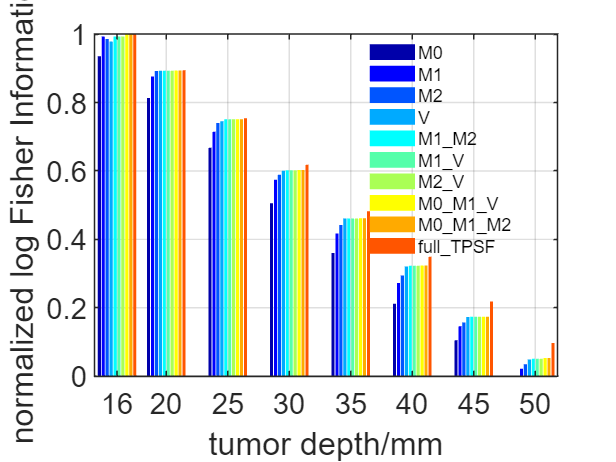

% -------- Create the figure at the given size
fig2 = figure;
ax2 = axes('Parent',fig2);


nMetric = numel(metrics);
nX      = numel(x);
data    = zeros(nX, nMetric);

% 1) 提取数据
for k = 1:nMetric
    data(:,k) = log10(opt_FI.(metrics{k}));
end

% 2) 归一化
minVal = min(data,[],'all');
maxVal = max(data,[],'all');
normData = (data - minVal) / (maxVal - minVal);  % 大小为 [nX x nMetric]

% 3) 绘制分组柱状图
% bar(ax2, x, normData, 'grouped');  % 每列为一个 metric，x 为横坐标

hBar = bar(ax2, x, normData, 'grouped');  % 返回 bar 对象数组

% 设置颜色（lines 是内置的 colormap，可替换为其他如 'parula', 'jet', 'cool'）
colors = jet(nMetric);  % 每个指标不同颜色

for k = 1:nMetric
    hBar(k).FaceColor = colors(k,:);     % 设置填充颜色
    hBar(k).EdgeColor = 'none';          % 去除边框
end


% 4) 图形美化
xlabel('tumor depth/mm');
ylabel('normalized log Fisher Information');
grid on; box(ax2,'on');

ax = gca;
ax.LineWidth = 1;
ax.FontSize = 8;
ax.FontName = 'Arial';

labels = metrics;
legend(labels, 'Location','best', 'Box','off', ...
    'FontSize',12, 'FontName','arial','Interpreter','none');

ax2.FontSize = 20;

plot(data_load.tpsfs(:,124))
tpsf_test = round(data_load.tpsfs(:,124));
mu_1 = sum(tpsf_test.*BinFlag.^1)/(sum(tpsf_test))  % mean m1
mu_2 = sum(tpsf_test.*BinFlag.^2)/(sum(tpsf_test))  % mean m1
mu_3 = sum(tpsf_test.*BinFlag.^3)/(sum(tpsf_test))  % mean m1
mu_4 = sum(tpsf_test.*BinFlag.^4)/(sum(tpsf_test))  % mean m1

rho_m1_m2 = (mu_3-mu_1*mu_2)./(sqrt(mu_2-mu_1.^2)*sqrt(mu_4-mu_2.^2))

numerator = mu_3 - 3*mu_1*mu_2 + 2*mu_1^3;

% 分母：sqrt( Var(M1) * Var(V) )
var_M1 = (mu_2 - mu_1^2);

% Var(V) 近似公式
var_V = ((mu_4 - mu_2^2) ...
    + 4*mu_1^2*(mu_2 - mu_1^2) ...
    - 4*mu_1*(mu_3 - mu_1*mu_2));

denominator = sqrt(var_M1 * var_V);

% 相关系数
rho_m1_v = numerator / denominator


% 分子：Cov(M2, V)
numerator = mu_4 - mu_2^2 - 2 * mu_1 * (mu_3 - mu_1 * mu_2);

% 分母：sqrt(Var(M2) * Var(V))
var_M2 = mu_4 - mu_2^2;

var_V = (mu_4 - mu_2^2) ...
    + 4 * mu_1^2 * (mu_2 - mu_1^2) ...
    - 4 * mu_1 * (mu_3 - mu_1 * mu_2);

denominator = sqrt(var_M2 * var_V);

% 相关系数
rho_m2_v = numerator / denominator

Em1 = sum(BinFlag.*tpsf_test,1)./sum(tpsf_test,1); % row vector
Em2 = sum(BinFlag.^2.*tpsf_test,1)/sum(tpsf_test,1);
Ev = Em2-Em1.^2;

J_m0_Ni = ones(size(tpsf_test));
J_m1_Ni = (BinFlag-Em1)./sum(tpsf_test,1); % col vector
J_m2_Ni = (BinFlag.^2-Em2)./sum(tpsf_test,1);
J_v_Ni = ((BinFlag-Em1).^2-Ev)./sum(tpsf_test,1);


var_m0 = sum(tpsf_test);
var_m1 = J_m1_Ni'*diag(tpsf_test)*J_m1_Ni;
var_m2 = J_m2_Ni'*diag(tpsf_test)*J_m2_Ni;
var_v = J_v_Ni'*diag(tpsf_test)*J_v_Ni;

cov_m0_m1 = 0;
rho_m0_m1 = cov_m0_m1./(sqrt(var_m0)*sqrt(var_m1))

cov_m0_m2 = 0;
rho_m0_m2 = cov_m0_m2./(sqrt(var_m0)*sqrt(var_m2))

cov_m0_v = 0;
rho_m0_v = cov_m0_v./(sqrt(var_m0)*sqrt(var_v))

[R, stats] = montecarlo_moments_corr(BinFlag, tpsf_test, 1e6);
R

var(stats,1,1)

histogram(stats(:,2)), hold on
histogram(Em1 + sqrt(var_m1) .* randn(1e6, 1))

digits(1000);                % 设置精度为 1000 位

rho_m1_m2 = 0.9
Sigma_m1_m2 = vpa([var_m1,       rho_m1_m2*sqrt(var_m1)*sqrt(var_m2);
    rho_m1_m2*sqrt(var_m1)*sqrt(var_m2),   var_m2      ])

% Sigma_m1_m2 = [var_m1,       0;
%    0,   var_m2      ];

% 计算逆矩阵
% invSigma_m1_m2 = inv(Sigma_m1_m2);
% % 计算 Fisher 信息量
% I_m1_m2 = [J_m1_Ni'*J_Ni_mua; J_m2_Ni'*J_Ni_mua]' * (Sigma_m1_m2 \ [J_m1_Ni'*J_Ni_mua; J_m2_Ni'*J_Ni_mua])

invSigma_m1_m2 = vpa((1/(1-rho_m1_m2.^2))*[1/var_m1,  -rho_m1_m2*(sqrt(var_m1)*sqrt(var_m2))^-1;
    -rho_m1_m2*(sqrt(var_m1)*sqrt(var_m2))^-1, 1/var_m2 ]);

vpa(Sigma_m1_m2*invSigma_m1_m2)

I_m1_m2 = [J_m1_Ni'*J_Ni_mua; J_m2_Ni'*J_Ni_mua]' * invSigma_m1_m2 * [J_m1_Ni'*J_Ni_mua; J_m2_Ni'*J_Ni_mua]

I_m1 = 1/var_m1.*(J_m1_Ni'*J_Ni_mua).^2
I_m2= 1/var_m2.*(J_m2_Ni'*J_Ni_mua).^2
I_v = 1/var_v.*(J_v_Ni'*J_Ni_mua).^2

I_m1+I_m2